# Getting started with the SP Cup 2022 dataset

Copyright 2022, The MathWorks, Inc.

## Set root folder and create audio datastore 

Set root to the folder containing all .wav recordings and .csv file with label assignments

root = ".\spcup_2022_training_part1";

Call out to helper function getSPCupDatastore, which associates wav files found in the folder to labels assigned in the csv table

ads = getSPCup2022Datastore(root);

## Validate number of total recordings for each class

countlabels(ads,UnderlyingDatastoreIndex=2)

ans = 5×3 table
    Label    Count    Percent
    _____    _____    _______

      0      1000       20   
      1      1000       20   
      2      1000       20   
      3      1000       20   
      4      1000       20   


## Inspect a random sample

Read

adss = shuffle(ads);
[data, info] = read(adss);
fs = info{1}.SampleRate;
x = data{1};
lab = data{2};
L = size(x,1);

Playback

soundsc(x,fs)

Plot

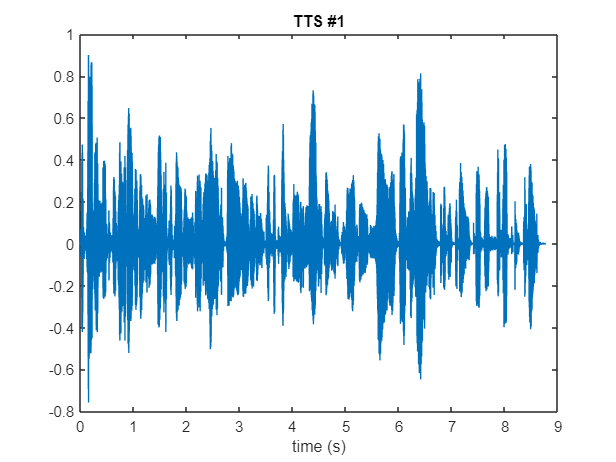

t = (1/fs) * (0:L-1)';
plot(t,x)
labText = "TTS #"+string(lab);
title(labText)
xlabel("time (s)")

## Extract features from a sample file

Example: extract MFCC from a sample recording and replicate a label for each of the recordings

WindowLength = 512;
OverlapLength = 384;
afe = audioFeatureExtractor('SampleRate',fs, ...
                            'Window',hann(WindowLength,'periodic'), ...
                            'OverlapLength',OverlapLength, ...
                            'mfcc',true);
setExtractorParams(afe,"mfcc","NumCoeffs",13)
featureMatrix = extract(afe,x);
size(featureMatrix)

ans =         1092          13


labels = repmat(lab,[size(featureMatrix,1),1]);
size(labels)

ans =         1092           1


## Extract MFCC features from all dataset

Example: extract MFCC from all recordings, and replicate a label for each of the recordings

Define Audio Feature Extraction parameters

WindowLength = 512;
OverlapLength = 384;
afe = audioFeatureExtractor('SampleRate',fs, ...
                            'Window',hann(WindowLength,'periodic'), ...
                            'OverlapLength',OverlapLength, ...
                            'mfcc',true);
setExtractorParams(afe,"mfcc","NumCoeffs",13)

Initialize cell arrays for the feature matrices and masks.

TrainingFeatures = {};
TrainingLabels= {};

Extract features and matching-size labels for all datastore using `parfor`. The following code runs on up to 8 cores in parallel, if available

numPartitions = 8;
tic
parfor ii = 1:numPartitions
    
    subads = partition(ads,numPartitions,ii);
    
    count = 1;
    numLocalFiles = length(subads.UnderlyingDatastores{1}.Files)
    localFeatures = cell(numLocalFiles,1);
    localLabels = cell(numLocalFiles,1);
    
    while hasdata(subads)
        
        % Create a training sentence
        [data,info] = read(subads);
        x = data{1};
        lab = data{2};
        fs = info{1}.SampleRate;
        
        % Compute features
        featureMatrix = extract(afe, x);
        featureMatrix(~isfinite(featureMatrix)) = 0;
        
        % Create label array with matching depth
        labels = repmat(lab,[size(featureMatrix,1),1]);

        localFeatures{count} = featureMatrix;
        localLabels{count} = labels;
        
        count = count + 1;
    end
    
    TrainingFeatures = [TrainingFeatures;localFeatures];
    TrainingLabels = [TrainingLabels;localLabels];
end
fprintf('Extracting features from all training data took %f seconds.\n',toc)

Extracting features from all training data took 45.878704 seconds.


Normalize features

sampleFeature = TrainingFeatures{1};
numFeatures = size(sampleFeature,2);
featuresMatrix = cat(1,TrainingFeatures{:});
M = mean(featuresMatrix);
S = std(featuresMatrix);
for index = 1:length(TrainingFeatures)
    f = TrainingFeatures{index};
    f = (f - M) ./ S;
    TrainingFeatures{index} = f; %#ok
end